# ergoCub Finger PID tuning

Copyright (C) 2023 Fondazione Istitito Italiano di Tecnologia (IIT)

All Rights Reserved.

## System identification and modelling 

### Read and plot datasets

#### Training Set

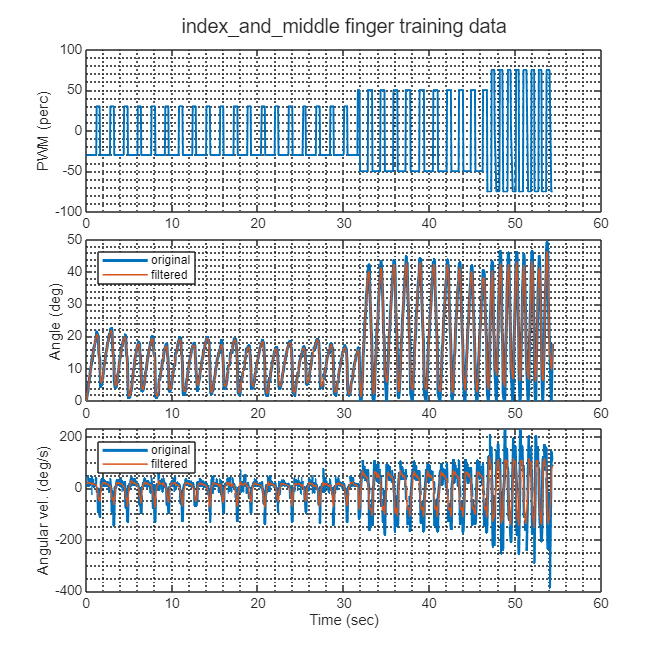


if(~exist('fname', 'var') ||  ~exist('fpath', 'var'))
    [fname, fpath] = uigetfile('*');
end
[pathstr, nameFile, ext] = fileparts(fname);

filter_constant = 1;
[training_table, Ts] = Reshape_dataset(fullfile(fpath,fname),  filter_constant, 1, 0, 2);

training_data = iddata(training_table.vel, training_table.pwm, Ts);
training_data.Name = "training";

f_train = figure('color', 'white','Position',[10 10 590 590]);
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(training_table.Time, training_table.pwm);
ylabel("PWM (perc)")
h2 = nexttile;
plot(training_table.Time, training_table.pos_uf,'LineWidth',2);
hold on
plot(training_table.Time, training_table.pos,'LineWidth',1);
ylabel("Angle (deg)")
legend({"original", "filtered"},'Location','northwest')
h3 = nexttile;
plot(training_table.Time, training_table.vel_uf ,'LineWidth',2);
hold on
plot(training_table.Time, training_table.vel,'LineWidth',1);


legend({"original", "filtered"},'Location','northwest')
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(strcat(nameFile, " finger training data"), Interpreter='none');

#### Validation Set

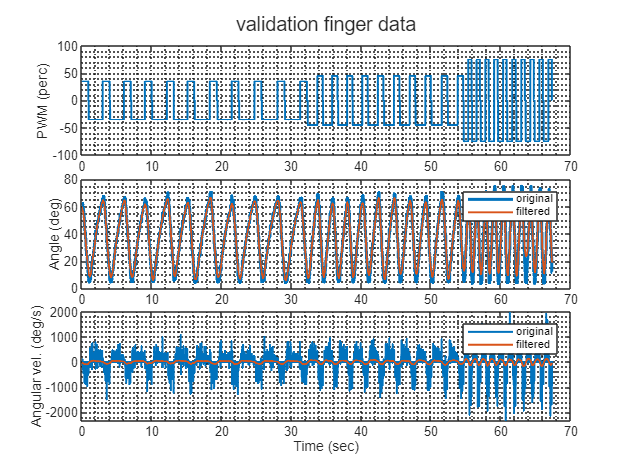

if(~exist('valid_name', 'var') ||  ~exist('valid_path', 'var'))
    [valid_name, valid_path] = uigetfile('*');
end
[pathstr, nameFile, ext] = fileparts(valid_name);

filter_constant = 15;
% validation_table = prepare_dataset(fullfile(valid_path, valid_name), Ts, filter_constant);
[validation_table, Ts] = Reshape_dataset(fullfile(valid_path, valid_name), filter_constant, 0, 0, 3);

validation_data = iddata(validation_table.vel, validation_table.pwm, Ts);
validation_data.Name = "validation";

figure('color', 'white');
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(validation_table.Time, validation_table.pwm);
ylabel("PWM (perc)")
h2 = nexttile;
plot(validation_table.Time, validation_table.pos_uf,'LineWidth',2);
hold on
plot(validation_table.Time, validation_table.pos,'LineWidth',1.2);
ylabel("Angle (deg)")
legend({"original", "filtered"})
h3 = nexttile;
plot(validation_table.Time, validation_table.vel_uf);
hold on
plot(validation_table.Time, validation_table.vel);

legend({"original", "filtered"})
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle(nameFile + " finger data")

### Run identification as process model

We target a continuous LTI model in the form


$$G(s) = \frac{k (s - z_1)}{(s - p_1) ( s - p_2)}$$


The poles can be real or complex conjugate. 

opt = procestOptions;
opt.InitialCondition =  "zero";
model = procest(training_data, "P2ZU", opt);

s = tf('s');
finger_tf = tf(model);
zpk(finger_tf)


ans =
 
  From input "u1" to output "y1":
  -18.848 (s+0.02426)
  --------------------
  (s+14.07) (s+0.7533)
 
Continuous-time zero/pole/gain model.
Model Properties


Plot results.

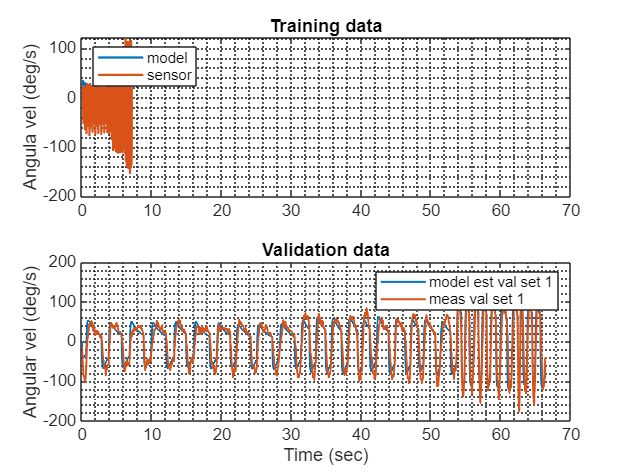

[rmse, fig_handle] = plot_results(finger_tf, training_data, validation_data, Ts, Ts);

disp(rmse)

     name: "Validation set 1 result"
    value: 22.6216179877105



finger_zpk = zpk(finger_tf);
poles = finger_zpk.P{1};
zeros = finger_zpk.Z{1};
k = finger_zpk.K;

tfu = k;

if(isreal(poles) && isreal(zeros))
    perc_uncertainty = 20;
    
    disp("Adding " + string(perc_uncertainty) + "% uncertainty to TF roots");

    for i=1:length(poles)
        upole = ureal("p" + string(i), poles(i), "Percentage", [-perc_uncertainty, perc_uncertainty]);
        tfu = tfu / (s - upole);
    end
    for i=1:length(zeros)
        uzero = ureal("z" + string(i), zeros(i), "Percentage", [-perc_uncertainty, perc_uncertainty]);
        tfu = tfu * (s - uzero);
    end
else
    tfu = finger_zpk;
end

Adding 20% uncertainty to TF roots


### Add integrator for position control

We change the IO relationship from  $\frac{\dot{\theta} }{u}$ to $\frac{\theta }{u}$  since we want to control the finger position.

tfu = tfu / s;

## Run autotuning

Here we define the specifications to tune the position controller in a robust way, and run the tuning algorithm.

#### Define tuning goals

Define the desired specifications.

select = 2;

switch select

    case (1)
        parSet = '001';
        disp('option 1 - SN 001')
        Ts_controller = 1e-3;   % sec
        responsetime = 0.25;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.02;       % fract relative
        maxOvershoot = 2;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (2) % for now equal to SN 001
        disp('option 2 - SN 002')
        parSet = '002';
        Ts_controller = 1e-3;   % sec
        responsetime = 0.4;     % sec
        dcerror = 0.001;        % perc
        peakerror = 1.00;       % fract relative
        maxOvershoot = 0;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
    case (3) %choose this one to play with parameters
        disp('option 3 - custom')
        parSet = 'cus';
        Ts_controller = Ts;   % sec
        responsetime = 0.5;     % sec
        dcerror = 0.005;        % perc
        peakerror = 1.1;       % fract relative
        maxOvershoot = 20;       % perc
        phase_margin = 80;      % deg
        gain_margin = 3;        % dB
end

option 2 - SN 002


par_summ = strcat('Ts controller: ', num2str(Ts_controller), ...
    ', responsetime: ', num2str(responsetime), ...
    ', dcerror: ', num2str(dcerror), ...
    ', peakerror: ', num2str(peakerror), ...
    ', Overshoot: ', num2str(maxOvershoot) );
disp(par_summ);

Ts controller:0.001, responsetime:0.4, dcerror:0.001, peakerror:1, Overshoot:0


Define the goals.

tfu.InputName = "u";
tfu.OutputName = "y";

Rtrack = TuningGoal.Tracking('r', 'y', responsetime, dcerror, peakerror);
Rov = TuningGoal.Overshoot('r', 'y', maxOvershoot);
Rmargin = TuningGoal.Margins('y', gain_margin, phase_margin);

hard_goals = Rtrack;
soft_goals = [Rmargin, Rov];

disp('hard_goals: tracking ');

hard_goals: tracking 


disp('soft_goals: margin, overshoot');

soft_goals: margin, overshoot


#### Tune up the controller

pid_type = 'PI';

[C, T] = design_robust_pid(tfu, soft_goals, hard_goals, pid_type);

Plot tuning results.

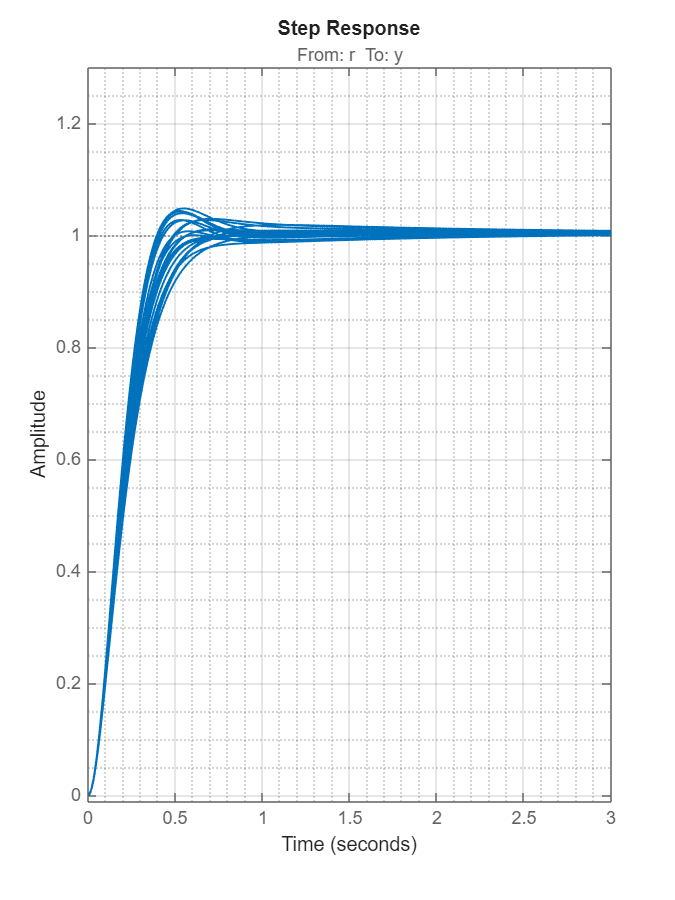

f_step = figure('color', 'white','Position',[10 10 900 1200]);
step(T, 3);
ylim([-0.01, 1.3])
grid('minor');

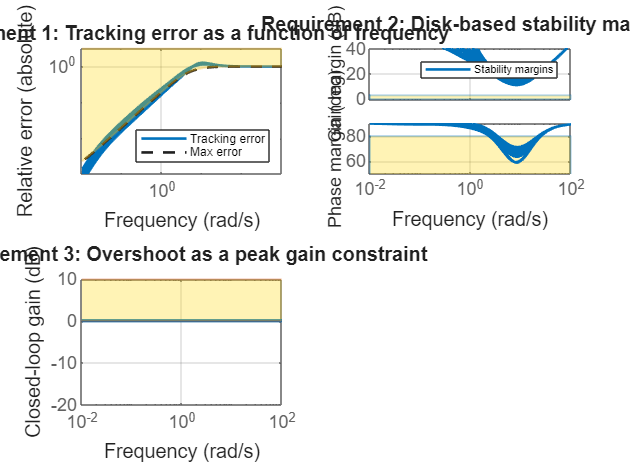

f_plots = figure('color', 'white');

viewGoal([hard_goals soft_goals], T)

Get the discretized controller.

Cz = c2d(C, Ts_controller, 'tustin')


Cz =
 
            Ts*(z+1)
  Kp + Ki * --------
            2*(z-1) 

  with Kp = -3.7, Ki = -2.71, Ts = 0.001
 
Sample time: 0.001 seconds
Discrete-time PI controller in parallel form.
Model Properties


table(["Kp", "Ki", "Kd"]', [Cz.Kp Cz.Ki Cz.Kd]', VariableNames = ["Param", "Value"])

ans = 3×2 table
    Param          Value      
    _____    _________________

    "Kp"     -3.70095487445961
    "Ki"     -2.71480789110521
    "Kd"                     0


% saveas(f_train, f_name);
% exportgraphics(f_train, f_name);
% exportgraphics(f_resume, f_name,'append',true);
% exportgraphics(f_plots, f_name,'append',true);
kappapi = Cz.Kp;
kappai = Cz.Ki;
kappadi = Cz.Kd;

%to save the kp, ki and kd coefficents uncomment the following line
%save(strcat('results/', nameFile,'-',parSet,'_',tYpe,'.mat'), 'nameFile','kappapi', 'kappai','kappadi')
% writematrix([nameFile , num2str(kappapi) , num2str(kappai) , num2str(kappadi)],strcat('results/', nameFile,'-',parSet,'_',tYpe,'.csv'))

% to obtain a pdf report uncomment the following  line 
% export('identification_tuning_v2.mlx',strcat('results/',nameFile,'-',parSet,'_',tYpe,'.pdf'), Format = "pdf", HideCode = true);